%% 清空工作变量，指定工作区间
clc;clear;close all;
cd 'E:\03_Master\11_matlab\Function_ProtableLIBS';
addpath(genpath('./FUN'))

# 数据集读取

% 数据读取
path = 'E:\03_Master\09_实验数据\20231030_classify';
path_Num = 6;
SpectrumFile_Num = 20;    %每一个类中有几个文件夹存放光谱/每一个文件夹有效光谱数量
Mean_Num = 10;
for i = 1 : path_Num
    filePath = [path, '\', num2str(i)];
    [S,wave] = csv2mat2(filePath);
    eval(['dataset',num2str(i),'=','S.dataset',';']);
end
% % 去除数据前5发
for i = 1 : path_Num
    eval(['dataset',num2str(i),'([1:5,16:20,31:35,46:50,61:65,76:80,91:95,106:110,121:125,136:140,151:155,166:170,181:185,196:200,211:215,226:230,241:245,256:260,271:275,286:290],:)','=','[]',';']);
%       eval(['dataset',num2str(i),'([1:5,16:20,31:35,46:50,61:65,76:80,91:95,106:110,121:125,136:140],:)','=','[]',';']);
end

% 数据合并
dataset = [];
data_All = [];
datashow = zeros(SpectrumFile_Num,12282);
for i = 1 : path_Num
    dataset_temp =  eval(['dataset',num2str(i)]);
    for j = 1 : SpectrumFile_Num
        datashow(j,:) = mean(dataset_temp((j-1)*Mean_Num+1:j*Mean_Num,:));
    end
    data_All = cat(1,data_All,datashow);
    dataset = cat(1,dataset,eval(['dataset',num2str(i)]));
end

# 选线（手选+机选）

datashow = data_All;
eleslec_names = {'c','H','O','N','K','Ca','Na','Mg'};
%***********************************************************************
line = mean(dataset);
[line,~] =  baseline_arPLS(line);

[peaks_find,elemnames] = autolineV4(line,wave,eleslec_names);

选峰完成
去重完成


writecell(elemnames,'result\waveslec.xlsx','WriteMode','overwrite')
writematrix(peaks_find,'result\waveslec.xlsx','Sheet',1,'Range','B1')
linewrite = [wave(:),line(:)];
writematrix(linewrite,'result\linewrite.csv','WriteMode','overwrite')

# 多数据集拼接

label = [1,2,3,4,5,6,7,8];
for i = 1 : size(label,2)
     eval(['data',num2str(i),'=','[dataset1(SampleNum*(i-1)+1:SampleNum*i,:);' ...
         ['dataset2(SampleNum*(i-1)+1:SampleNum*i,:);dataset3(SampleNum*(i-1)+1:SampleNum*i,:);' ...
         'dataset4(SampleNum*(i-1)+1:SampleNum*i,:)]'],';']);
end
dataset = [data1;data2;data3;data4;data5;data6;data7;data8];
data1_mean = mean(data1);
data2_mean = mean(data2);
data3_mean = mean(data3);
data4_mean = mean(data4);
data5_mean = mean(data5);
data6_mean = mean(data6);
data7_mean = mean(data7);
data8_mean = mean(data8);
[data1_mean,~] =  baseline_arPLS(data1_mean);
[data2_mean,~] =  baseline_arPLS(data2_mean);
[data3_mean,~] =  baseline_arPLS(data3_mean);
[data4_mean,~] =  baseline_arPLS(data4_mean);
[data5_mean,~] =  baseline_arPLS(data5_mean);
[data6_mean,~] =  baseline_arPLS(data6_mean);
[data7_mean,~] =  baseline_arPLS(data7_mean);
[data8_mean,~] =  baseline_arPLS(data8_mean);
data3_mean = data3_mean';
data4_mean = data4_mean';
data5_mean = data5_mean';
data6_mean = data6_mean';
data7_mean = data7_mean';
data8_mean = data8_mean';

#  数据降维

% 重新加载手动挑选后的数据集
waveslec = readcell("result1\waveslec1.xlsx",'Sheet',1);
waveslec_name = waveslec(:,1);
waveslec_num = cell2mat(waveslec(:,2:end));
waveslec_real = waveslec_num(:,6);
% name = waveslec_name;
% datat1 = DataSlec(data1,wave,1,1,waveslec_real);
% datat2 = DataSlec(data2,wave,1,1,waveslec_real);
% datat3 = DataSlec(data3,wave,1,1,waveslec_real);
% [data_PCA3, COEFF3, sum_explained3, n3,latent3]=fun_pca3(data);
name = waveslec_name;
datat1 = DataSlec(dataset,wave,1,1,waveslec_real);
label = 1:6;
label1 = repelem(label',200,1); 
[re,zhi,zhimat] = FUN_SVM(Seccal_Out,label1,6);
[re_knn,zhi_knn,zhimat_knn] = FUN_KNNCV(Seccal_Out,label1,6,1);

# 添加标签打乱数据集

% data1 = dataset;
% data2 = dataset;
% data3 = dataset;
label = 1:5;
label1 = repelem(label',200,1);
label2 = repelem(label',200,1);
label3 = repelem(label',200,1);

% 打乱数据集
index1 = randperm(size(datat1,1));
index1 = index1(:);
data1_rand = datat1(index1,:);
label1_rand = label1(index1,:);

index2 = randperm(size(datat2,1));
index2 = index2(:);
data2_rand = datat2(index2,:);
label2_rand = label2(index2,:);

index3 = randperm(size(datat3,1));
index3 = index3(:);
data3_rand = datat3(index3,:);
label3_rand = label3(index3,:);

data_rand = [data1_rand;data2_rand;data3_rand];
label_rand = [label1_rand;label2_rand;label3_rand];

# 分类

% data_PCArand = data_PCA3(index,:);
% label_rand = label(index,:);
 [re,zhi,zhimat] = FUN_SVM(data_rand,label_rand,5);
% re_mat = zeros(50,6);
% for i = 1:50
     [re_knn,zhi_knn,zhimat_knn] = FUN_KNNCV(data_rand,label_rand,5,1);
%      re_mat(i,:) = zhi_knn;
% end

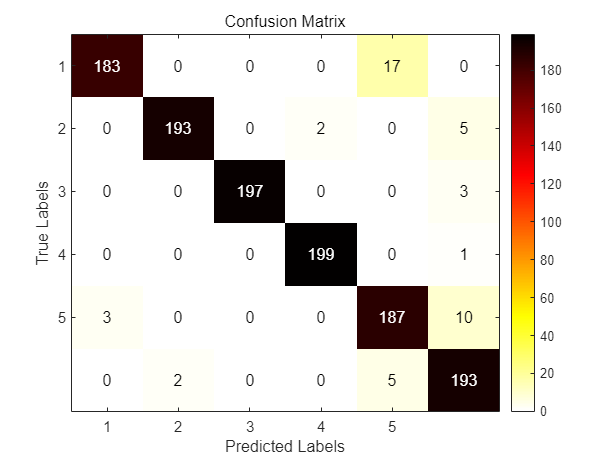

confusion_matrix = confusionmat(re(:,1),re(:,2));
sum1 = sum(confusion_matrix,2);
[m,n] = size(confusion_matrix);
% for i =1: m
%     confusion_matrix(i,:)=confusion_matrix(i,:)/sum1(i)
% end
draw_cm(confusion_matrix);
set(gca,'XTick',1:1:5);
set(gca,'XTickLabel',{'1','2','3','4','5'})
set(gca,'YTick',1:1:5);
set(gca,'YTickLabel',{'1','2','3','4','5'})

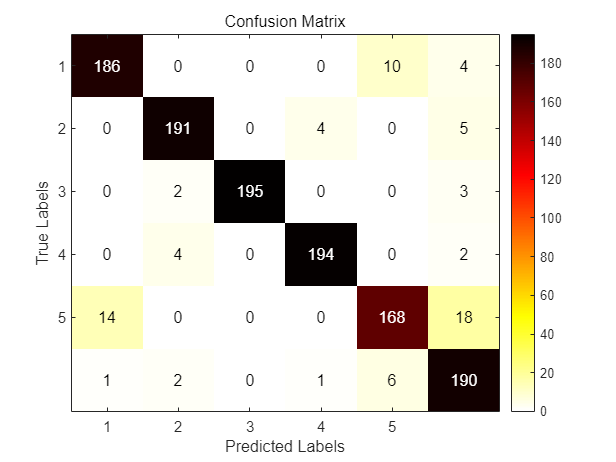

confusion_matrix_knn = confusionmat(re_knn(:,1),re_knn(:,2));
sum1 = sum(confusion_matrix_knn,2);
[m,n] = size(confusion_matrix_knn);
% for i =1: m
%     confusion_matrix(i,:)=confusion_matrix(i,:)/sum1(i)
% end
draw_cm(confusion_matrix_knn);
set(gca,'XTick',1:1:5);
set(gca,'XTickLabel',{'1','2','3','4','5'})
set(gca,'YTick',1:1:5);
set(gca,'YTickLabel',{'1','2','3','4','5'})

datatool = [data_rand,label_rand];